Hello World!

s = daq.createSession('ni');
daq.getDevices();
ans.ID

ans = 'Dev1'

addAnalogInputChannel(s, 'Dev1', 1, 'voltage');
s

s = Data acquisition session using National Instruments hardware:
   Will run for 1 second (1000 scans) at 1000 scans/second.
   Number of channels: 1
      index Type Device Channel MeasurementType      Range       Name
      ----- ---- ------ ------- --------------- ---------------- ----
      1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
   
Properties, Methods, Events


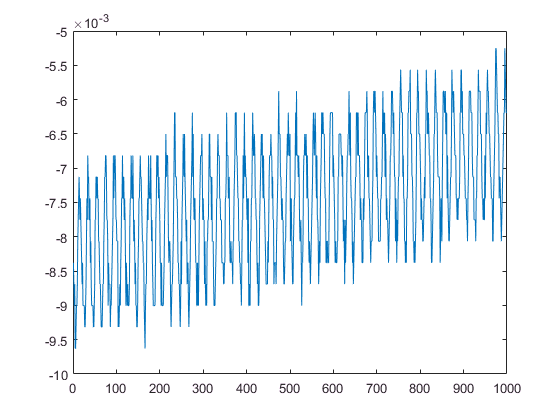

data = s.startForeground();
plot(data)

s.Rate = 1000

s = Data acquisition session using National Instruments hardware:
   Will run for 1 second (1000 scans) at 1000 scans/second.
   Number of channels: 1
      index Type Device Channel MeasurementType      Range       Name
      ----- ---- ------ ------- --------------- ---------------- ----
      1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
   
Properties, Methods, Events


s.DurationInSeconds = 0.1

s = Data acquisition session using National Instruments hardware:
   Will run for 0.1 seconds (100 scans) at 1000 scans/second.
   Number of channels: 1
      index Type Device Channel MeasurementType      Range       Name
      ----- ---- ------ ------- --------------- ---------------- ----
      1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
   
Properties, Methods, Events


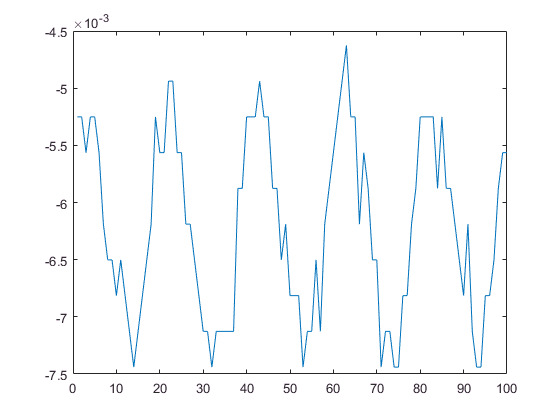

data2 = s.startForeground();
plot(data2)